# AERO4600 Automatic Flight Control Systems Main file

clc
clear
close all
%%
% States
% [u,v,w,p,q,r,\phi,\theta,\psi,X,Y,Z]
%
% Inputs 
% [thrust, elevator, aileron, rudder, flaps]

## Initial Set Up

FlightData = LoadFlightData_aircraft2_75kts_CG2();

load ICs_aircraft2_75Kts_CG2

DT = 0.01;          % Integration time interval
T0 = DT;            % Simulation start time
TF = 200;            % Termination time for simulation
n_pts = round((TF-T0)/DT+1);
X = zeros(12,n_pts);
U = zeros(5,n_pts);
T = zeros(1,n_pts);

X(:,1) = X0;
U(:,1) = U0;
T(1)   = DT;


## Trim Condition

Xg    = zeros(6,1);
V_trim  = sqrt(X0(1)^2+X0(2)^2+X0(3)^2); % (m/s)
alt0    = -X0(12); % (m)
alt0ft  = alt0/0.3048; % (ft)
alpha_0 = X0(3)/V_trim; % (rad)
beta_0  = 0/57.3; % (rad)
gamma   = 0/57.3; % (rad)
phi_0   = 0/57.3; % (rad)
dp      = U0(1); % (fraction of travel 0-1)
de      = U0(2); % (rad)
da      = U0(3)/57.3; % (rad)
dr      = U0(4)/57.3; % (rad)
df      = U0(5); % (rad)

## Q1a

% Transfer Function
[A,B] = peturbAB(X0,Xg,U0,FlightData);
A_lon = A([1 3 5 8],[1 3 5 8]);
B_lon = B([1 3 5 8], 1:2);
A_lat = A([2 4 6 7 9],[2 4 6 7 9]);
B_lat = B([2 4 6 7 9], [3 4]);

C = [0 -1 0 V_trim];    % Vertical Speed

[Num, Den] = ss2tf(A_lon, B_lon, C, [0 0],2);
Num(abs(Num) < 1e-07) = 0;
Gtf = minreal(tf(Num, Den));
Gtf = zpk(Gtf)

Gtf =
 
        8.57 (s-16.89) (s+12.79) (s+0.04162)
  ------------------------------------------------
  (s^2 + 0.03407s + 0.06989) (s^2 + 4.67s + 10.92)
 
Continuous-time zero/pole/gain model.



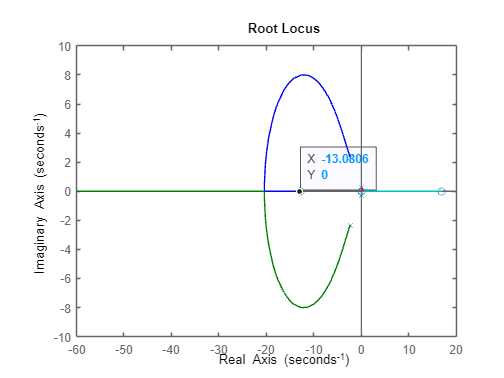

rlocus(Gtf)

function [A,B] = peturbAB(X0,Xg,U0,FlightData)

A = zeros(12,12);
B = zeros(12,5);
delta_x = 1e-6; % Perturbation for finite difference

% Compute Xdot at the trim condition
[ForceCoeff, MomentCoeff] = aero4600_aero(X0,Xg, X0, U0, FlightData);
Xdot0 = aero4600_motion(X0, ForceCoeff, MomentCoeff, FlightData);

% A Matrix
for i = 1:12
    X_perturb = X0;
    X_perturb(i) = X_perturb(i) + delta_x; %Adding a small peturbation away from equilibrium
    
    % Calculating Xdot with perturbed state
    [ForceCoeff_pert, MomentCoeff_pert] = aero4600_aero(X_perturb, Xg, X_perturb, U0, FlightData);
    Xdot_pert = aero4600_motion(X_perturb, ForceCoeff_pert, MomentCoeff_pert, FlightData);
    A(:, i) = (Xdot_pert - Xdot0) / delta_x;
end

% B matrix
for i = 1:5
    U_perturb = U0;
    U_perturb(i) = U_perturb(i) + delta_x;

    [ForceCoeff_pert, MomentCoeff_pert] = aero4600_aero(X0, Xg, X0, U_perturb, FlightData);
    Xdot_pert = aero4600_motion(X0, ForceCoeff_pert, MomentCoeff_pert, FlightData);
    B(:, i) = (Xdot_pert - Xdot0) / delta_x;
end

end